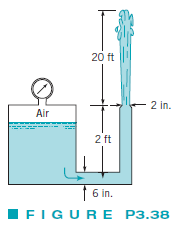

# given

u = symunit;
gamma = 62.4*u.lbf/u.ft^3;
rho = 1.94*u.slug/u.ft^3;
g = 32.2*u.ft/u.s^2;
H = 20*u.ft;

# state 1

p1 = sym('p1');
V1 = 0;
z1 = 2*u.ft;

# state 2

% -------------------
p2 = 0;
V2 = 0;
z2 = 22*u.ft;
% -------------------

# Bernoulli's Equation

eqn = sym.zeros(2,1);
p1 = solve(p1+rho*V1^2/2+gamma*z1 == p2+rho*V2^2/2+gamma*z2);
p1 = rewrite(p1, u.psi);